# 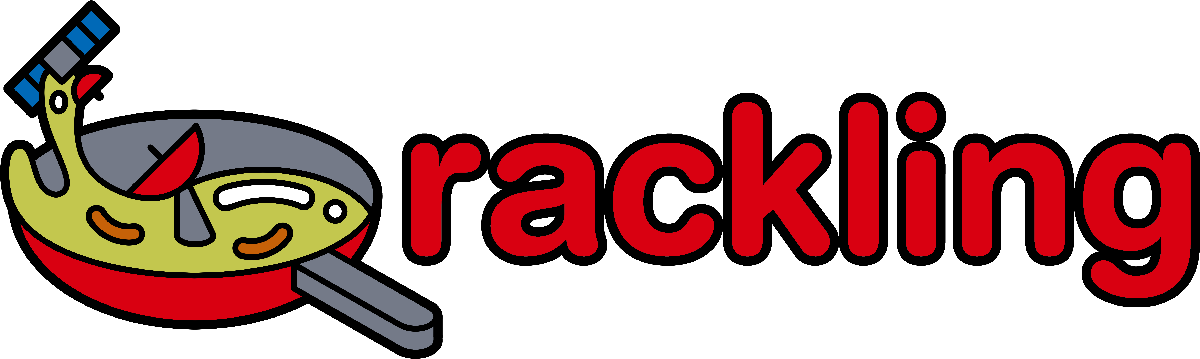

# Getting Started with Qrackling

*A MATLAB toolbox for modelling quantum key distribution between satellite*

## Description

Qrackling is a flexible object-oriented MATLAB toolbox for simulating quantum key distribution (QKD) between satellites and ground stations. It is easily extended and can be used to replicate satellite QKD presented in the literature as well as explore the features present within them. Qrackling has been developed at Heriot-Watt University in the Free-Space QKD group to aid in the design and development of the Hub Optical Ground Station (HOGS).

## Features

- Multiple qkd protocols:  BB84, Decoy state BB84, Coherent One-Way, Differential phase shift

- Data for a range of detectors (APD, SNSPD) (Collected or extrapolated for various of the shelf devices)

- Loss models: (Geometric, Optical, Point and Track, Atmospheric, Turbulence)

- (Optional) Integration with [libRadtran](http://www.libradtran.org/doku.php), software for radiative transfer allowing the inclusion of transmission and radiance simulations that can be tailored to QKD scenario being studied

## Example Usage

As an example to get up and running we have available predefined functions to construct a satellite matching the Satellite Platform for Optical Quantum Communications (SPOQC) mission and ground station according to the Hub Optical Ground Station (HOGS). For the full details of each you can run each of the following in the MATLAB console to view them:

For this example we'll pick 785nm for the communications wavelength.

qkd_wavelength = 785; % nm

Our HOGS object will look like so:

hogs = HubOpticalGroundStation(qkd_wavelength)

hogs =   Ground_Station with properties:

                 toolbox_ground_station: []
    Background_Count_Rate_File_Location: 'none'
          Sky_Brightness_Store_Location: 'none'
                                 Camera: [1x1 beacon.Camera]
                                 Beacon: [1x1 beacon.Gaussian_Beacon]
               Atmosphere_File_Location: []
                               Latitude: 55.9097
                              Longitude: -3.3200
                               Altitude: 10
                          Velocity_East: NaN
                         Velocity_North: NaN
                            Velocity_Up: NaN
                          Location_Name: ""
                     useSatCommsToolbox: 0
                             N_Position: 1
                               Detector: [1x1 components.Detector]
                       Background_Rates: []
            Light_Pollution_Count_Rates: 0
     

And for our SPOQC object we can also choose a predefined satellite pass that is known to pass overhead from the point of view of HOGS, the following time and date strings are available:

and the final argument "which" is just an index to choose out of the four available times for each date.

spoqc = SatellitePlatformForOpticalQuantumCommunications( ...
    qkd_wavelength, ...
    "25/12/2022, 08:44, 14:50, 16:22, 17:55", 1)

spoqc =   Satellite with properties:

                           Name: "SPOQC"
       Orbit_Data_File_Location: ''
                          Times: [25-Dec-2022 06:00:00    25-Dec-2022 06:00:01    25-Dec-2022 06:00:02    25-Dec-2022 06:00:03    25-Dec-2022 06:00:04    25-Dec-2022 06:00:05    25-Dec-2022 06:00:06    25-Dec-2022 06:00:07    ...    ]
                       Protocol: [1x1 protocol.bb84]
            Protocol_Efficiency: 1
                        Surface: []
                         Beacon: [1x1 beacon.Flat_Top_Beacon]
                         Camera: [1x1 beacon.Camera]
                       Latitude: [3601x1 double]
                      Longitude: [3601x1 double]
                       Altitude: [3601x1 double]
                  Velocity_East: [3601x1 double]
                 Velocity_North: [3601x1 double]
                    Velocity_Up: [3601x1 double]
                  Location_Name: ""
         

Next we'll choose a qkd protocol, decoy BB84 for this example, and then run the pass simulation. Here "nodes.QkdPassSimulation" takes as its first argument a receiver and as second a transmitter, these can be either a satellite or ground station. In this case the order we have chosen will define a situation in which the satellite and ground station are in a downlink configuration, alternatively the following would allow us to investigate an uplink configration:

Protocol = protocol.decoyBB84();
result = nodes.QkdPassSimulation(hogs, spoqc, Protocol);

Finally we can call "plotResult" on the above result object to get an overview of the satellite qkd pass.

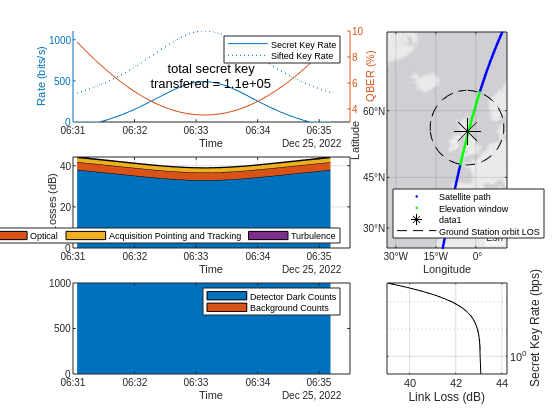

downlink_figure =   Figure (1: protocol.decoyBB84 simulation from Satellite:  to Ground Station: ) with properties:

      Number: 1
        Name: 'protocol.decoyBB84 simulation from Satellite:  to Ground Station: '
       Color: [0.9400 0.9400 0.9400]
    Position: [680 1086 560 420]
       Units: 'pixels'

  Show all properties


downlink_figure = result.plotResult(hogs, spoqc, "mask", "Elevation")